clear all
addpath(genpath('~/tools/matlab/shared_functions'));
n = 120;
% Collected data
d=[];
d.cookies_morning = 30+7*randn(1,n);
d.ch_present      = binornd(zeros(1,n)+1, 0.5);
ch0 = find(d.ch_present == 0);
ch1 = find(d.ch_present == 1);
d.cookies_evening(ch0) = 5+2*randn(1, length(ch0));
d.cookies_evening(ch1) = 10+2*randn(1, length(ch1));
d.cookies_evening(find(d.cookies_evening<0)) = 0;
d.h               = 8;



## GRID SEARCH

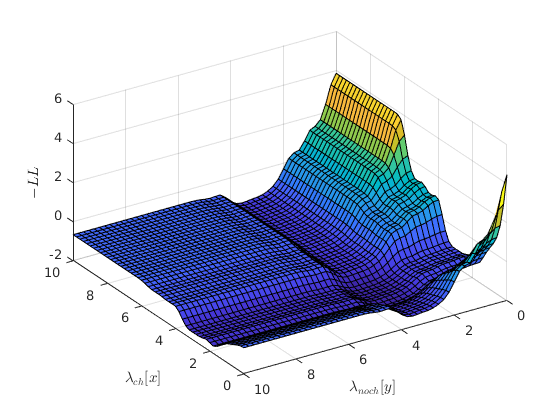

L = []; %likelihood function 
ch1_vals = 0:0.2:10;
ch0_vals = 0:0.2:10;
E=[];
for c1 = 1:numel(ch1_vals)
    for c2 = 1:numel(ch0_vals)
        E(c1, c2) = m1_error([ch1_vals(c1), ch0_vals(c2)],d);
    end
end
[X,Y] = meshgrid(ch1_vals, ch0_vals);
f=figure;

surf(X,Y,E');
xlabel('$\lambda_{ch} [x]$', 'Interpreter',"latex")
ylabel('$\lambda_{noch} [y]$', 'Interpreter',"latex")
zlabel('$-LL$', 'Interpreter',"latex")

## FIT


lb = [0 0]; % lower boundaries
ub = [10 10]; % upper boundaries
%X0 = [15 15]; % startin position
X0 = lb + rand(1,2).*ub

X0 =     4.6910    2.8682



[X, err] = bads(@m1_error, X0, lb, ub, [], [], [], [], d);

Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.44228               1                              Uncertainty test
     0           4        -1.44228               1            Initial mesh      
     1           6        -1.44228             0.5             Refine grid      Train
     2          10        -1.75758             0.5    Incremental search (ES-ell)      
     2          14        -1.75758            0.25             Refine grid      
     3          16        -1.88401            0.25    Successful search (ES-ell)      
     3          18        -1.95434            0.25    Incremental search (ES-wcm)      
     3          26        -1.96061           0.125             Refine grid      Train
     4          34        -1.96061          0.0625             Refine grid      
     5          36        -1.99257          0.0625    Successful search (ES-ell

X

X =     1.8058    3.5840


E2=[];P=[];
for r = 1:5
    % parameter limits

    lb = [0 0]; % lower boundaries
    ub = [10 10]; % upper boundaries
    %X0 = [15 15]; % startin position
     X0 = lb + rand(1,2).*ub
    
    [X, err] = bads(@m1_error, X0, lb, ub, [], [], [], [], d);
    P(r,:) = X;
    E2(r) = err;
end

X0 =     0.6866    8.6400


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -0.23273               1                              Uncertainty test
     0           4       -0.899169               1            Initial mesh      
     1           6        -1.01394             0.5             Refine grid      Train
     2           7        -1.46742             0.5    Successful search (ES-wcm)      
     2          10        -1.71346             0.5    Incremental search (ES-wcm)      
     2          11         -1.7874             0.5    Incremental search (ES-wcm)      
     2          12        -1.79305             0.5    Incremental search (ES-wcm)      
     2          13        -1.79445             0.5    Incremental search (ES-wcm)      
     2          14        -1.80869             0.5    Incremental search (ES-ell)      
     2          18        -1.80869            0.25             

X0 =     9.0525    0.4917


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        0.741544               1                              Uncertainty test
     0           4        -1.13265               1            Initial mesh      
     1           6        -1.13265             0.5             Refine grid      Train
     2           7        -1.48066             0.5    Incremental search (ES-wcm)      
     2           8        -1.63631             0.5    Incremental search (ES-wcm)      
     2           9        -1.65676             0.5    Incremental search (ES-ell)      
     2          14        -1.65676            0.25             Refine grid      
     3          15        -1.74696            0.25    Incremental search (ES-wcm)      
     3          16        -1.77985            0.25    Incremental search (ES-wcm)      
     3          17        -1.80935            0.25    Incremental sea

X0 =     3.4382    2.0730


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.36905               1                              Uncertainty test
     0           4        -1.48654               1            Initial mesh      
     1           6        -1.48654             0.5             Refine grid      Train
     2           9        -1.50171             0.5    Incremental search (ES-wcm)      
     2          13        -1.50171            0.25             Refine grid      
     3          15        -1.55723            0.25    Incremental search (ES-ell)      
     3          21        -1.79222             0.5         Successful poll      
     4          24        -1.82023             0.5    Incremental search (ES-ell)      
     4          29        -1.82023            0.25             Refine grid      Train
     5          31        -1.86859            0.25    Incremental search (ES-e

X0 =     9.4139    4.7144


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -0.68441               1                              Uncertainty test
     0           4       -0.732424               1            Initial mesh      
     1           6       -0.732424             0.5             Refine grid      Train
     2           8        -1.49952             0.5    Successful search (ES-wcm)      
     2           9        -1.79207             0.5    Incremental search (ES-wcm)      
     2          18        -1.79207            0.25             Refine grid      Train
     3          21         -1.8274            0.25    Incremental search (ES-ell)      
     3          26         -1.8274           0.125             Refine grid      Train
     4          34        -1.83435          0.0625             Refine grid      
     5          35        -1.85959          0.0625    Successful search (E

X0 =     2.7977    5.2751


Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2         -1.5124               1                              Uncertainty test
     0           4         -1.5124               1            Initial mesh      
     1           6         -1.5124             0.5             Refine grid      Train
     2           8        -1.62155             0.5    Incremental search (ES-wcm)      
     2          14        -1.62155            0.25             Refine grid      
     3          16         -1.6257            0.25    Incremental search (ES-wcm)      
     3          17        -1.84023            0.25    Successful search (ES-wcm)      
     3          19        -1.84475            0.25    Incremental search (ES-ell)      
     3          22        -1.84826            0.25    Incremental search (ES-ell)      
     3          26        -1.84826           0.125             Refine 

E2

E2 =    -1.8774   -1.8774   -1.8774   -1.8774   -1.8773


P

P =     2.8752    4.1350
    2.8744    4.1381
    2.8752    4.1393
    2.8782    4.1316
    2.8672    4.1396
